Presetting.

format("default");
clc;
clear;

# How to get reasonable ADC sample interval

## Step 1: Calculate the relationship between ADC energy consumption and sampling frequency

在`ADC_sample_frequency_vs_extra_current`中已经得到了ADC的采样频率与额外电流的关系符合线性关系，这里将表达式写在下面。

syms a b N_ps
I_extra = a * N_ps + b;

这里的额外电流对应的是较长一段时间内的平均电流。**如果使用瞬时电流，或者希望将ADC与开发板统一看作一个阻值恒定的电阻，只需要令**$a=0$**，**$b=I_{\text{ADC}}$**即可**。

### Step 2: Calculate Discharge Rate vs. ADC Samples Per Second

将整个开发板看作一个阻值恒定的电阻，这意味着电流和电压满足欧姆定律：$U=IR$。

$U_{\text{thr}}$表示的是阈值电压，这里主要考虑到的是**放电公式并不是一个线性函数，因此随着电压下降，电容的放电速率也会下降**。如果希望忽略这一影响，可以：

- 使用平均下降值，即计算出电压从$U_0
$下降到$U_{\text{thr}}$的时间$T_{\text{thr}}$，计算$\Delta U = \Delta T \times ((U_0 - U_{\text{thr}})/T_{\text{thr}})$。

- 令$U_{\text{thr}}=U_0$，即“悲观地”认为电压总是以最快的速率下降。

syms U t U0 I_board C

R = U0 / (I_extra + I_board);     
tau = R * C;
dischargingEquiv = U == U0 * exp(-t/tau);
syms U_thr
T_discharging(U) = solve(dischargingEquiv, t);
U_discharging(t) = solve(dischargingEquiv, U);
diffU_discharging(t) = diff(U_discharging, t);
DeltaU_diff = (1/N_ps) * -diffU_discharging(T_discharging(U_thr));
disp(DeltaU_diff);

$$\frac{U_{\mathrm{thr}}\,\left(I_{\mathrm{board}}+b+N_{\mathrm{ps}}\,a\right)}{C\,N_{\mathrm{ps}}\,U_{0}}$$

## Step 3: Find a suitable sampling frequency

将相关数值带入即得到ADC采样间隔与电压监测分辨率的关系。

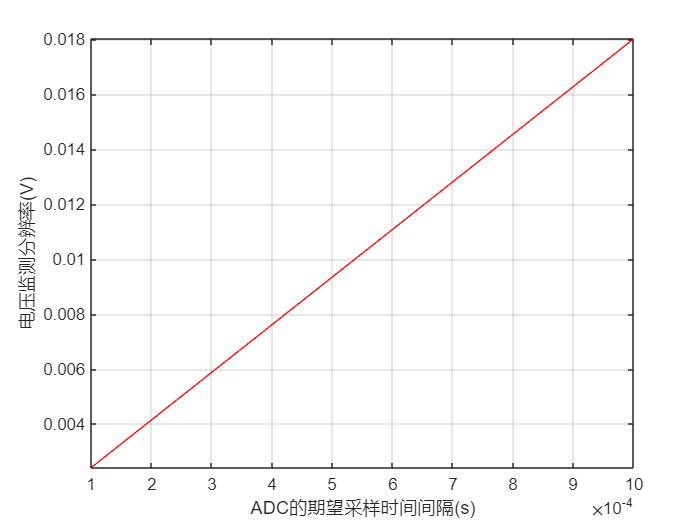

syms T_adc
DeltaU_func(U0, U_thr, I_board, a, b, N_ps, C) = DeltaU_diff;

% Demo 1:
% U0 = 3.3V, U_thr = 2.6V, I_board = 0.45mA, a = 0.0018e-5, b = 0.789e-5, 
% C = 20uF

demo1(T_adc) = DeltaU_func(3.3, 2.5, 0.45*1e-3, 0.0018*1e-5, 0.789*1e-5, 1/T_adc, 20*1e-6);
fplot(demo1(T_adc), [100e-6, 1000e-6], 'r')
ylabel("电压监测分辨率(V)")
xlabel("ADC的期望采样时间间隔(s)")
grid on

## Step 4

或者我们调换自变量与因变量，探究电压精确度与ADC采样间隔的关系。

syms deltaU
deltaUEquiv = deltaU == DeltaU_diff;
N_expect = solve(deltaUEquiv, N_ps)

$$N\_expect = -\frac{I_{\mathrm{board}}+b}{a-\frac{C\,U_{0}\,\mathrm{deltaU}}{U_{\mathrm{thr}}}}$$

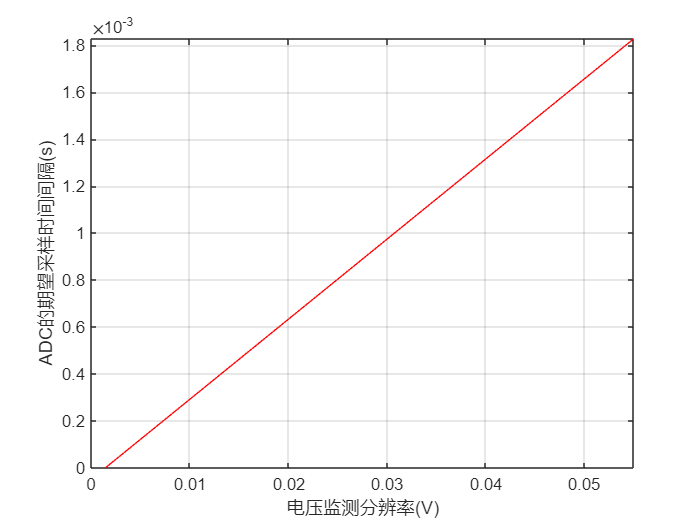

Nexpect_func(U0, U_thr, I_board, a, b, deltaU, C) = N_expect;

% Demo 2:
% U0 = 3.3V, U_thr = 2.7V, I_board = 0.35mA, a = 0.0018e-5, b = 0.789e-5, 
% C = 10uF

demo2(deltaU) = 1 / Nexpect_func(3.3, 2.7, 0.35*1e-3, 0.0018*1e-5, 0.789*1e-5, deltaU, 10*1e-6);
fplot(demo2(deltaU), [0.001, 0.055], 'r')
xlim([0, inf])
ylim([0, inf])
xlabel("电压监测分辨率(V)")
ylabel("ADC的期望采样时间间隔(s)")
grid on